puzzleImage = imread("Puzzle_34.jpg"); 
puzzleMask = segmentPuzzle34(puzzleImage); 

Let's have a look at these images

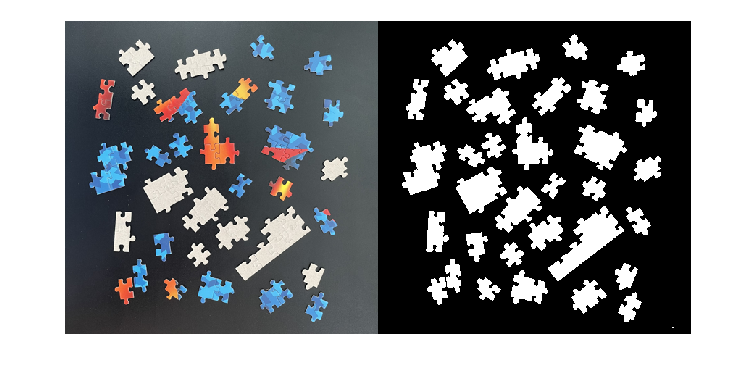

montage({puzzleImage,puzzleMask})

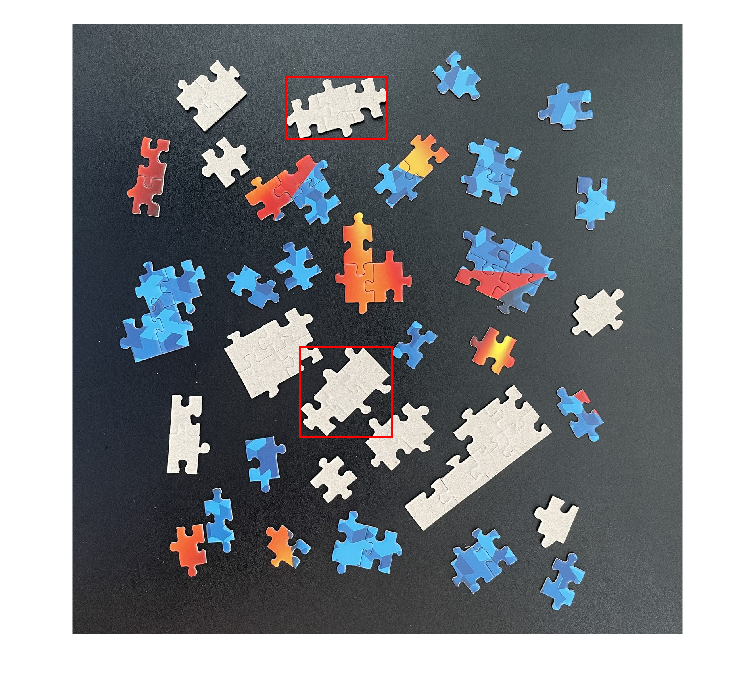


[threePieceMask, threePieceProperties] = Filter3MaskRegions(puzzleMask);

[threePieceLinearMask, threePieceLinearProperties] = Filter3MaskRegionsLinear(threePieceMask);

threePieceLinearBoxes = regionprops('table',threePieceLinearMask,"BoundingBox");


puzzleImageBoxed = insertShape(puzzleImage,"Rectangle",threePieceLinearBoxes.BoundingBox,"color","red","LineWidth",5); 
figure, imshow(puzzleImageBoxed)